% --- Linearity Check ---
t = 0:0.001:0.5;

% Define two different input amplitudes
u1 = ones(size(t));      % step input amplitude = 1
u2 = 2 * ones(size(t)); % step input amplitude = 2

% Simulate BOTH through the system properly
y1 = lsim(sys_speed, u1, t);   % response to input=1
y2 = lsim(sys_speed, u2, t);   % response to input=2

% Check linearity: y2 should equal exactly 2*y1
error_linearity = max(abs(y2 - 2*y1));
fprintf('Max linearity error: %.2e\n', error_linearity);

Max linearity error: 0.00e+00



if error_linearity < 1e-10
    disp('✅ SYSTEM IS LINEAR: y(2u) = 2*y(u)');
else
    disp('❌ SYSTEM IS NON-LINEAR');
end

✅ SYSTEM IS LINEAR: y(2u) = 2*y(u)



% --- Also test superposition ---
% Linearity = Homogeneity + Superposition
u3 = u1 + u2;            % combined input = 3
y3 = lsim(sys_speed, u3, t);
y1_plus_y2 = y1 + y2;    % sum of individual responses

error_superposition = max(abs(y3 - y1_plus_y2));
fprintf('Max superposition error: %.2e\n', error_superposition);

Max superposition error: 1.39e-17



if error_superposition < 1e-10
    disp('✅ SUPERPOSITION HOLDS');
else
    disp('❌ SUPERPOSITION FAILS');
end

✅ SUPERPOSITION HOLDS


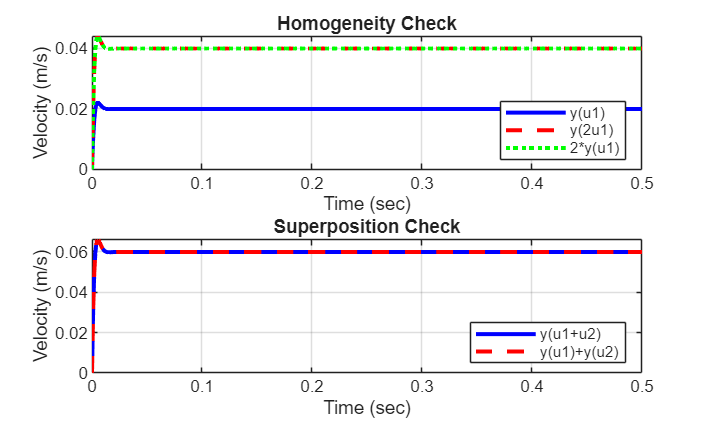


% --- Plot ---
figure('Color','w');
subplot(2,1,1)
plot(t, y1, 'b', 'LineWidth', 2); hold on;
plot(t, y2, 'r--', 'LineWidth', 2);
plot(t, 2*y1, 'g:', 'LineWidth', 2);
title('Homogeneity Check');
xlabel('Time (sec)');
ylabel('Velocity (m/s)');
legend('y(u1)', 'y(2u1)', '2*y(u1)', 'Location', 'southeast');
grid on;

subplot(2,1,2)
plot(t, y3, 'b', 'LineWidth', 2); hold on;
plot(t, y1_plus_y2, 'r--', 'LineWidth', 2);
title('Superposition Check');
xlabel('Time (sec)');
ylabel('Velocity (m/s)');
legend('y(u1+u2)', 'y(u1)+y(u2)', 'Location', 'southeast');
grid on;